# SV models

- Prepare stochastic volatility models

- Identify a SVAR using Cholesky

- Checking TV features of sigma in estimation/IRF/forecast



clear
close all
rehash path

addpath ../sandbox
addpath ../bear


## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];


## Prepare data and a reduced-form model

inputTbx = tablex.fromCsv("SV.csv");

estimStart = datex.q(1971,2);
estimEnd = datex.q(2020,1);
estimSpan = datex.span(estimStart, estimEnd);

meta = model.Meta( ...
    endogenous=["YER", "HICSA", "STN"], ...
    units="", ...
    exogenous=[], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=20, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);

dataH = model.DataHolder(meta, inputTbx);


## Stochastic-volatiliy models

Standard (CogleySargentSV)


estimatorR1 = estimator.CogleySargentSV(meta);

modelR1 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR1 ...
    , stabilityThreshold=Inf ...
);
modelR1.Estimator.Settings

ans =   CogleySargentSV with properties:

                              Burnin: 0
                           Exogenous: [3×1 logical]
                      BlockExogenous: 0
                      Autoregression: [3×1 double]
                             Lambda1: 0.1000
                             Lambda2: 0.5000
                             Lambda3: 1
                             Lambda4: [3×1 double]
                             Lambda5: 1.0000e-03
    HeteroskedasticityAutoRegression: 1
             HeteroskedasticityShape: 1.0000e-03
             HeteroskedasticityScale: 1.0000e-03


Random inertia


estimatorR2 = estimator.RandomInertiaSV(meta);

modelR2 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR2 ...
    , stabilityThreshold=Inf ...
);
modelR2.Estimator.Settings

ans =   RandomInertiaSV with properties:

    HeteroskedasticityAutoRegressionVariance: 0.0100
                                      Burnin: 0
                                   Exogenous: [3×1 logical]
                              BlockExogenous: 0
                              Autoregression: [3×1 double]
                                     Lambda1: 0.1000
                                     Lambda2: 0.5000
                                     Lambda3: 1
                                     Lambda4: [3×1 double]
                                     Lambda5: 1.0000e-03
            HeteroskedasticityAutoRegression: 1
                     HeteroskedasticityShape: 1.0000e-03
                     HeteroskedasticityScale: 1.0000e-03


large models (Carriero) 


estimatorR3 = estimator.CarrieroSV(meta);

modelR3 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR3 ...
    , stabilityThreshold=Inf ...
);
modelR3.Estimator.Settings

ans =   CarrieroSV with properties:

                              Burnin: 0
                           Exogenous: [3×1 logical]
                      BlockExogenous: 0
                      Autoregression: [3×1 double]
                             Lambda1: 0.1000
                             Lambda2: 0.5000
                             Lambda3: 1
                             Lambda4: [3×1 double]
                             Lambda5: 1.0000e-03
    HeteroskedasticityAutoRegression: 1
             HeteroskedasticityShape: 1.0000e-03
             HeteroskedasticityScale: 1.0000e-03


## Indentify a SVAR using Cholesky (without reordering)

Standard


identChol = identifier.Cholesky(order=[]);

modelS1 = model.Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();
info1 = modelS1.presample(1000);


 Presampling model.Structural (CogleySargentSV) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [39×1 double]
                     F: [3×3 double]
                     L: {196×1 cell}
                   phi: [0.2646 5.3876e-04 0.1405]
              sigmaAvg: [9×1 double]
                  sbar: [3×1 double]
              lambda_t: {196×1 cell}
               sigma_t: {196×1 cell}
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.6595    0.0492    0.0783
    0.0226    0.6382    0.0606
   -0.0130    0.0138    1.1270
    0.0036    0.0031   -0.0097
    0.1023    0.1161    0.0369
    0.0010    0.0065   -0.0804
    0.0455    0.0013   -0.0112
    0.0012    0.0588   -0.0015
    0.0159   -0.0039   -0.0467
    0.0024    0.0032    0.0049


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.6595    0.0492    0.0783
    0.0226    0.6382    0.0606
   -0.0130    0.0138    1.1270
    0.0036    0.0031   -0.0097
    0.1023    0.1161    0.0369
    0.0010    0.0065   -0.0804
    0.0455    0.0013   -0.0112
    0.0012    0.0588   -0.0015
    0.0159   -0.0039   -0.0467
    0.0024    0.0032    0.0049


Random inertia


modelS2 = model.Structural(reducedForm=modelR2, identifier=identChol);
modelS2.initialize();
info2 = modelS2.presample(1000);


 Presampling model.Structural (RandomInertiaSV) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS2.Presampled{1}

ans = struct with fields:
                  beta: [39×1 double]
                 omega: 10000
                     F: [3×3 double]
                     L: {196×1 cell}
                   phi: [0.2825 3.5842e-04 0.1998]
              sigmaAvg: [9×1 double]
                 gamma: [0.8901 0.9603 1.0188]
                  sbar: [3×1 double]
              lambda_t: {196×1 cell}
               sigma_t: {196×1 cell}
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


modelS2.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [3×3 double]


modelS2.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.5014    0.0243    0.0146
   -0.0999    0.6768    0.0514
    0.0143    0.0283    1.0578
    0.0381    0.0118    0.0094
    0.0690    0.0916    0.0268
   -0.0225   -0.0124   -0.0258
    0.0626    0.0035    0.0119
   -0.0102    0.0757    0.0274
    0.0037   -0.0167   -0.0128
    0.0292   -0.0013   -0.0211


modelS2.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.5014    0.0243    0.0146
   -0.0999    0.6768    0.0514
    0.0143    0.0283    1.0578
    0.0381    0.0118    0.0094
    0.0690    0.0916    0.0268
   -0.0225   -0.0124   -0.0258
    0.0626    0.0035    0.0119
   -0.0102    0.0757    0.0274
    0.0037   -0.0167   -0.0128
    0.0292   -0.0013   -0.0211


Large models


modelS3 = model.Structural(reducedForm=modelR3, identifier=identChol);
modelS3.initialize();
info3 = modelS3.presample(1000);


 Presampling model.Structural (CarrieroSV) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS3.Presampled{1}

ans = struct with fields:
                  beta: [39×1 double]
                     F: [3×3 double]
                     L: {196×1 cell}
                   phi: 1.0409
              sigmaAvg: [9×1 double]
                  sbar: [3×1 double]
              lambda_t: {196×1 cell}
               sigma_t: {196×1 cell}
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


modelS3.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [3×3 double]


modelS3.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.7393    0.1015    0.2855
    0.0428    0.5622    0.4855
   -0.0572    0.0799    1.0976
    0.0587   -0.0463    0.0063
   -0.0352    0.1236    0.0812
   -0.0070   -0.0319   -0.1060
    0.0151   -0.0135    0.0353
    0.0542    0.2153    0.0785
    0.0296   -0.0197   -0.0834
   -0.0307    0.0014   -0.0537


modelS3.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.7393    0.1015    0.2855
    0.0428    0.5622    0.4855
   -0.0572    0.0799    1.0976
    0.0587   -0.0463    0.0063
   -0.0352    0.1236    0.0812
   -0.0070   -0.0319   -0.1060
    0.0151   -0.0135    0.0353
    0.0542    0.2153    0.0785
    0.0296   -0.0197   -0.0834
   -0.0307    0.0014   -0.0537


## Impulse responses

Standard

respTbx1 = modelS1.simulateResponses();
respTbx1 = tablex.apply(respTbx1, prctileFunc);
respTbx1 = tablex.flatten(respTbx1);

respTbx1

respTbx1 = 24×9 timetable
     Time                      YER___DEM                                  YER___SUP                                 YER___POL                                HICSA___DEM                          HICSA___SUP                            HICSA___POL                             STN___DEM                             STN___SUP                           STN___POL          
    _______    _________________________________________    _____________________________________    ________________________________________    ___________________________________    ________________________________    ______________________________________    ________________________________    

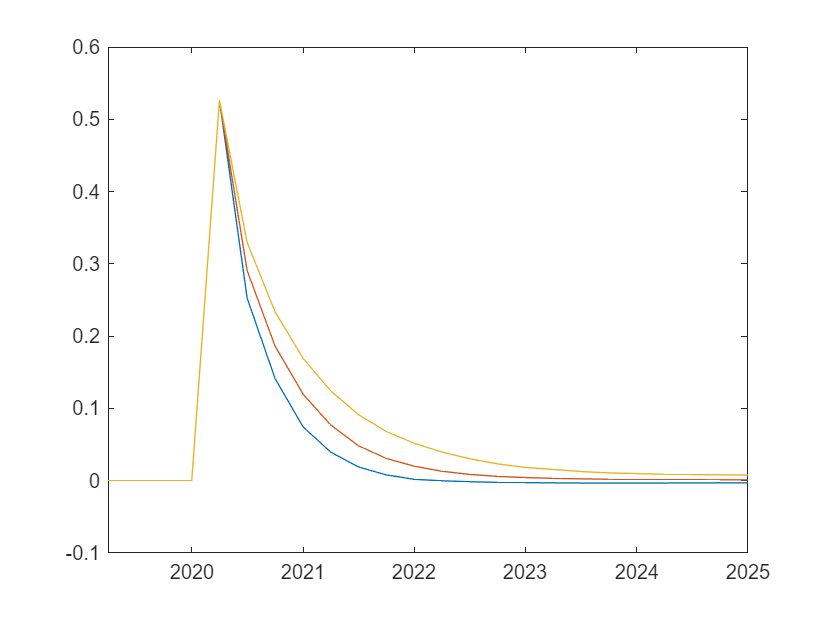

ans =   3×1 Line array:

  Line
  Line
  Line



tablex.plot(respTbx1,"YER___DEM")

Random-inertia

respTbx2 = modelS2.simulateResponses();
respTbx2 = tablex.apply(respTbx2, prctileFunc);
respTbx2 = tablex.flatten(respTbx2);

respTbx2

respTbx2 = 24×9 timetable
     Time                    YER___DEM                                  YER___SUP                                 YER___POL                               HICSA___DEM                          HICSA___SUP                            HICSA___POL                             STN___DEM                             STN___SUP                           STN___POL          
    _______    ______________________________________    _______________________________________    ______________________________________    ___________________________________    ________________________________    ______________________________________    ________________________________    _

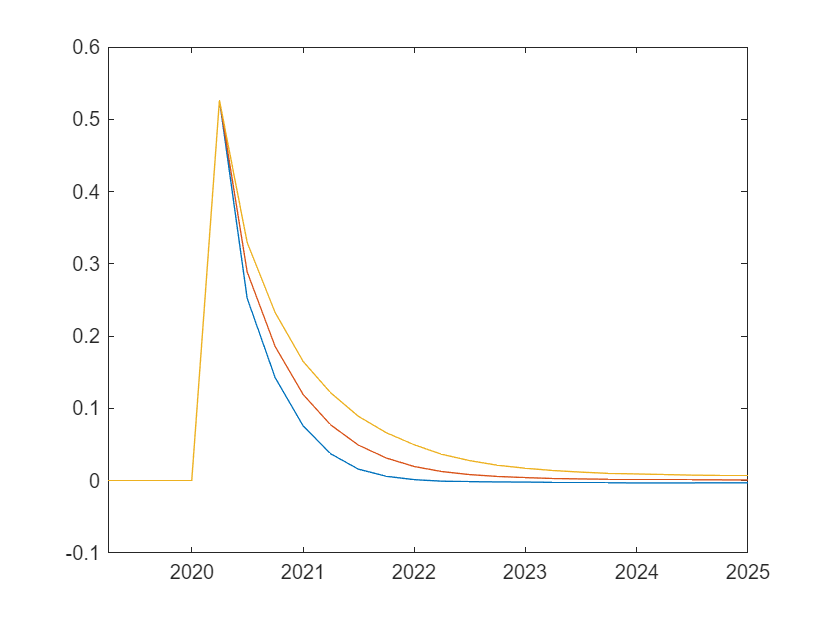

ans =   3×1 Line array:

  Line
  Line
  Line



tablex.plot(respTbx2,"YER___DEM")

Large models

respTbx3 = modelS3.simulateResponses();
respTbx3 = tablex.apply(respTbx3, prctileFunc);
respTbx3 = tablex.flatten(respTbx3);

respTbx3

respTbx3 = 24×9 timetable
     Time                      YER___DEM                                  YER___SUP                                  YER___POL                                  HICSA___DEM                             HICSA___SUP                         HICSA___POL                          STN___DEM                           STN___SUP                          STN___POL          
    _______    _________________________________________    ______________________________________    _______________________________________    _________________________________________    ________________________________    ________________________________    ________________________________    

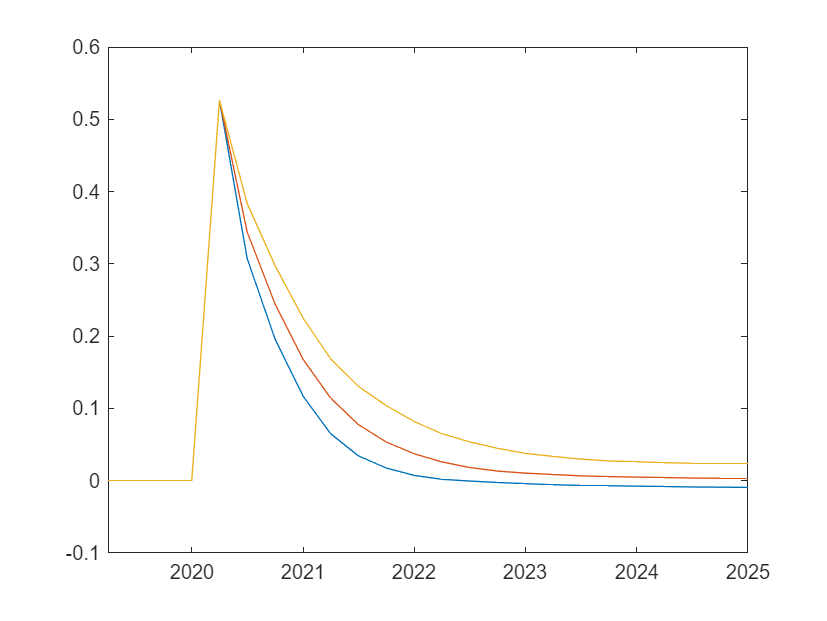

ans =   3×1 Line array:

  Line
  Line
  Line



tablex.plot(respTbx3,"YER___DEM")

## Unconditional forecast 


fcastStart = datex.shift(modelS1.Meta.EstimationEnd, -10);
fcastEnd = datex.shift(modelS1.Meta.EstimationEnd, 0);
fcastSpan = datex.span(fcastStart, fcastEnd);


Standard

fcastTbx1 = modelS1.forecast(fcastSpan);
fcastPrctileTbx1 = tablex.apply(fcastTbx1, prctileFunc);
fcastPrctileTbx1 = tablex.flatten(fcastPrctileTbx1);

fcastTbx1

fcastTbx1 = 15×6 timetable
     Time           YER             HICSA             STN           resid_YER       resid_HICSA       resid_STN  
    _______    _____________    _____________    _____________    _____________    _____________    _____________

    2016-Q3    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2016-Q4    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q1    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q2    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double

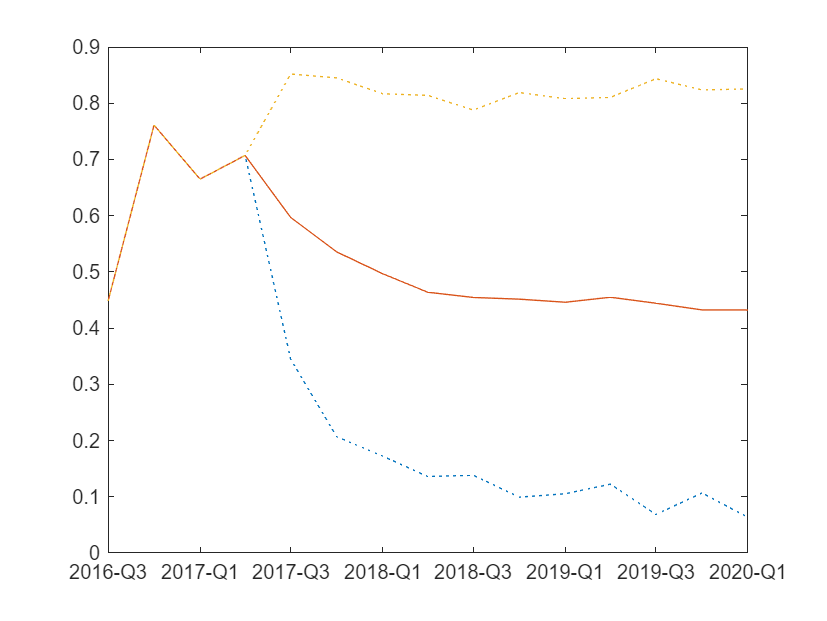


tablex.plot( ...
    fcastPrctileTbx1, "YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);

Random inertia

fcastTbx2 = modelS2.forecast(fcastSpan);
fcastPrctileTbx2 = tablex.apply(fcastTbx2, prctileFunc);
fcastPrctileTbx2 = tablex.flatten(fcastPrctileTbx2);

fcastTbx2

fcastTbx2 = 15×6 timetable
     Time           YER             HICSA             STN           resid_YER       resid_HICSA       resid_STN  
    _______    _____________    _____________    _____________    _____________    _____________    _____________

    2016-Q3    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2016-Q4    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q1    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q2    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double

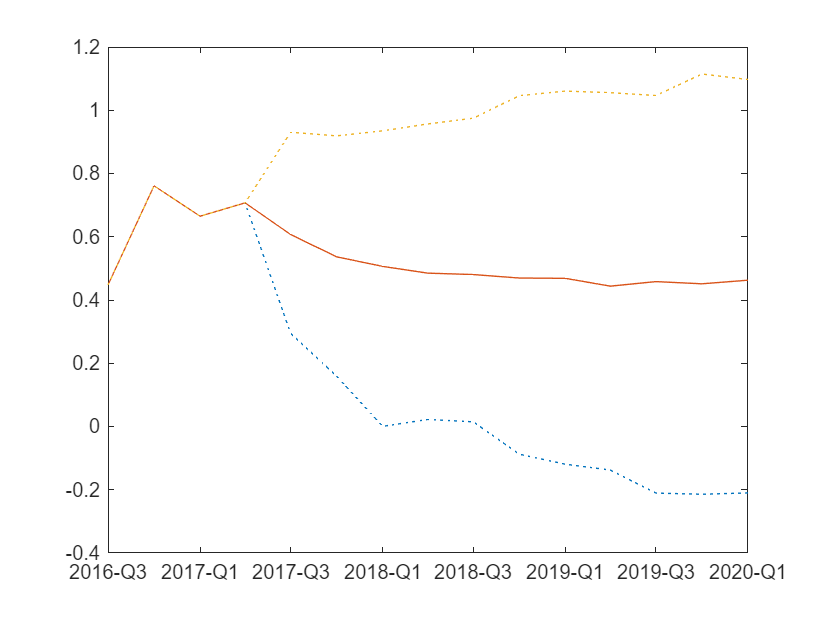


tablex.plot( ...
    fcastPrctileTbx2, "YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);

Large models

fcastTbx3 = modelS3.forecast(fcastSpan);
fcastPrctileTbx3 = tablex.apply(fcastTbx3, prctileFunc);
fcastPrctileTbx3 = tablex.flatten(fcastPrctileTbx3);

fcastTbx3

fcastTbx3 = 15×6 timetable
     Time           YER             HICSA             STN           resid_YER       resid_HICSA       resid_STN  
    _______    _____________    _____________    _____________    _____________    _____________    _____________

    2016-Q3    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2016-Q4    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q1    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q2    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double

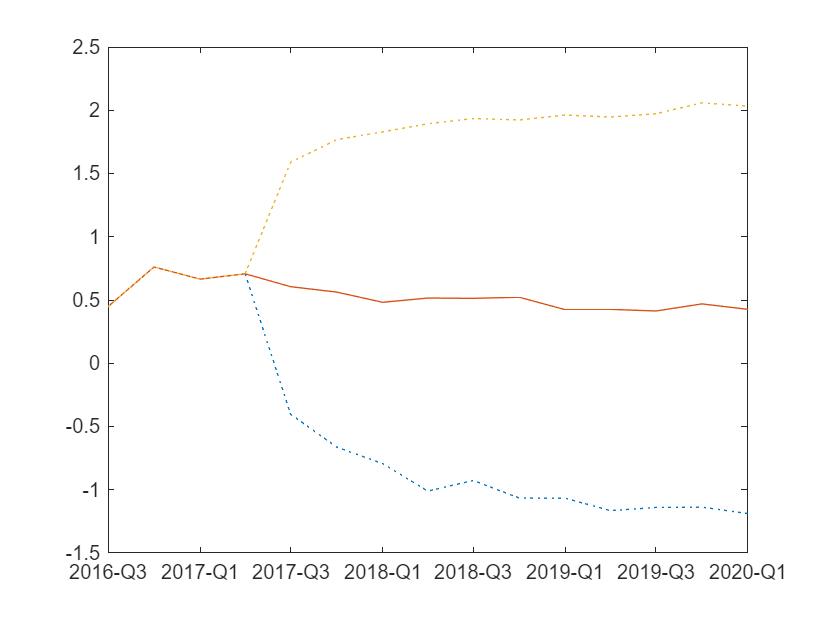


tablex.plot( ...
    fcastPrctileTbx3, "YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);